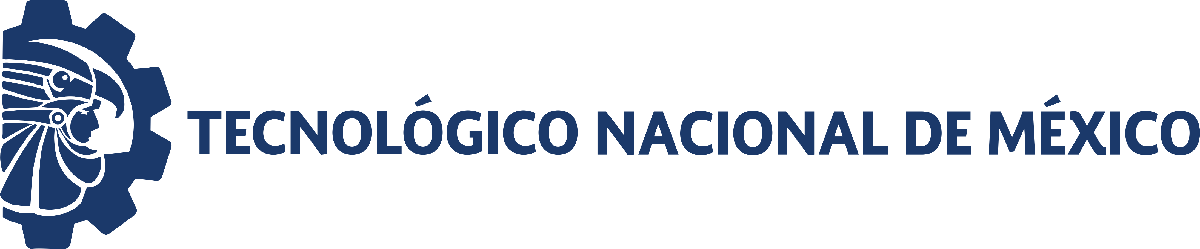                                 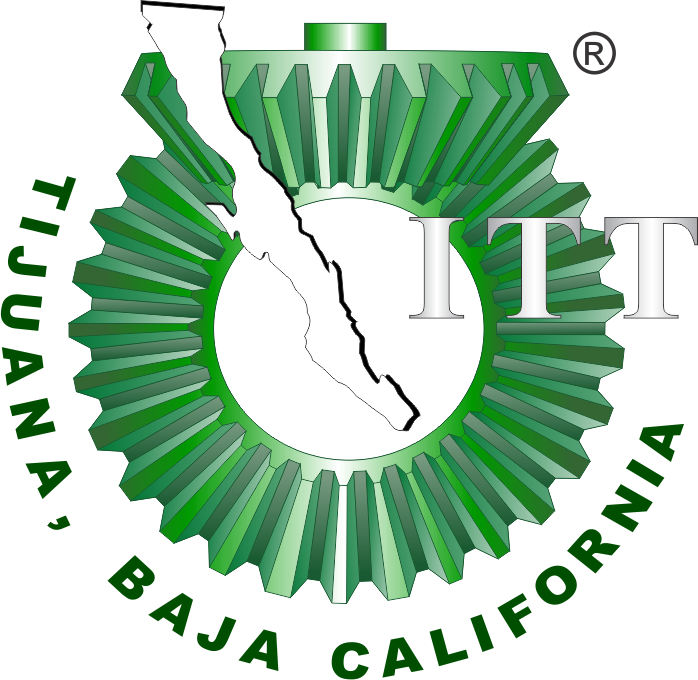

# Práctica 2: Sistema Presa-Depredador de Lotka-Volterra

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

**Objetivo: **Solucionar las ecuaciones de Lotka-Volterra para estudiar e ilustrar su dinámica en series de tiempo y plano de fase. El sistema presa-depredador se formula mediante las siguientes EDOs de primer orde:


$$\overset{\ldotp }{x} =\alpha x-\beta \textrm{xy}$$



$$\overset{\ldotp }{y} =\delta \textrm{xy}-\gamma y$$


con los valores de los parámetros $\alpha =0\ldotp 5$,$\beta =0\ldotp 01$,$\delta =0\ldotp 001$ y $\gamma =0\ldotp 2$, y las condiciones iniciales $x\left(0\right)=x_0 =75$ y $y\left(0\right)=y_0 =75$.

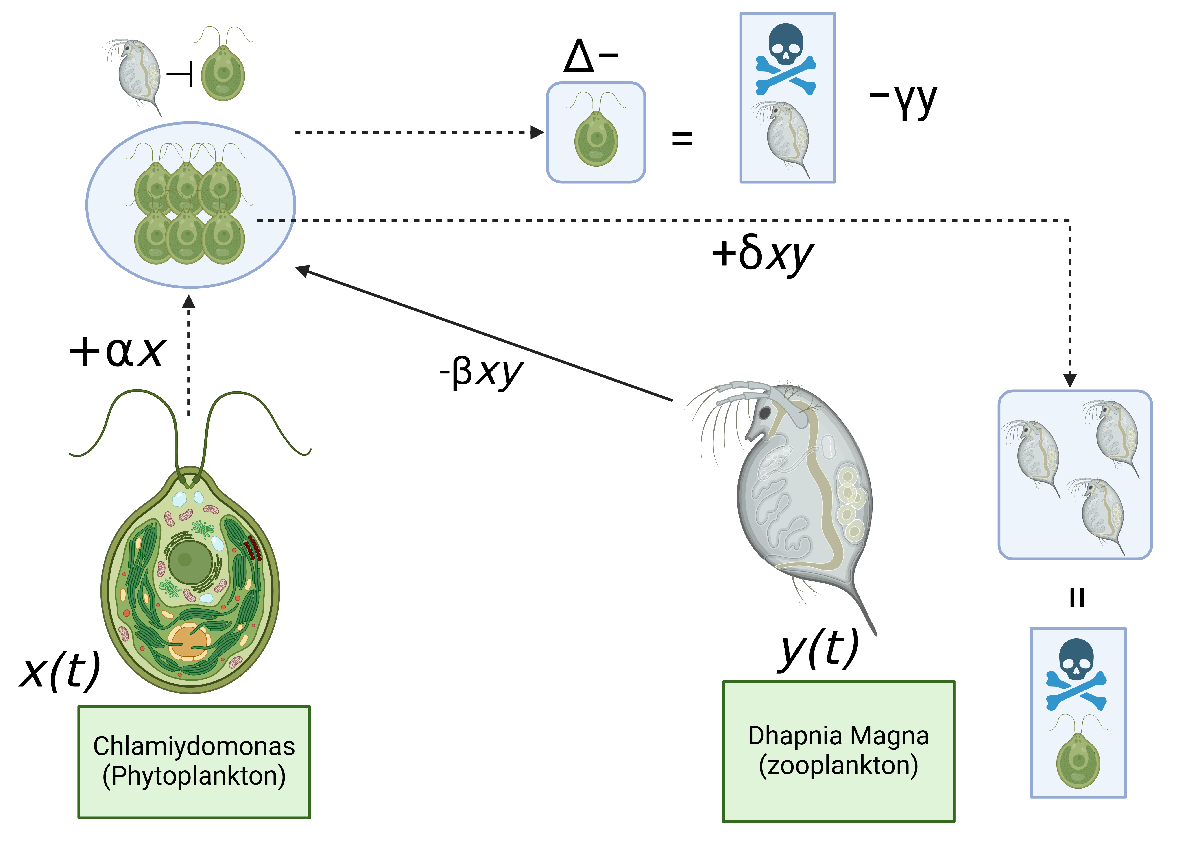

Figure. The phytoplankton population$x\left(t\right)$ grows exponentially with a reproductive rate $+\alpha x$, indicating that without predators, the population of Chlamydonomas would increase indefinitely [positive feedback]. Daphnia feed on Chlamydonomas which reduces the phytoplankton population with a proportional rate $-\beta \textrm{xy}$ [positive feedback]. The energy obtained by Daphnia translates into an increase in their population with a conversion rate of $+\delta \textrm{xy}$. The Daphnia population decreases naturally with a mortality rate $-\gamma y\;$[negative feedback].

## Información general

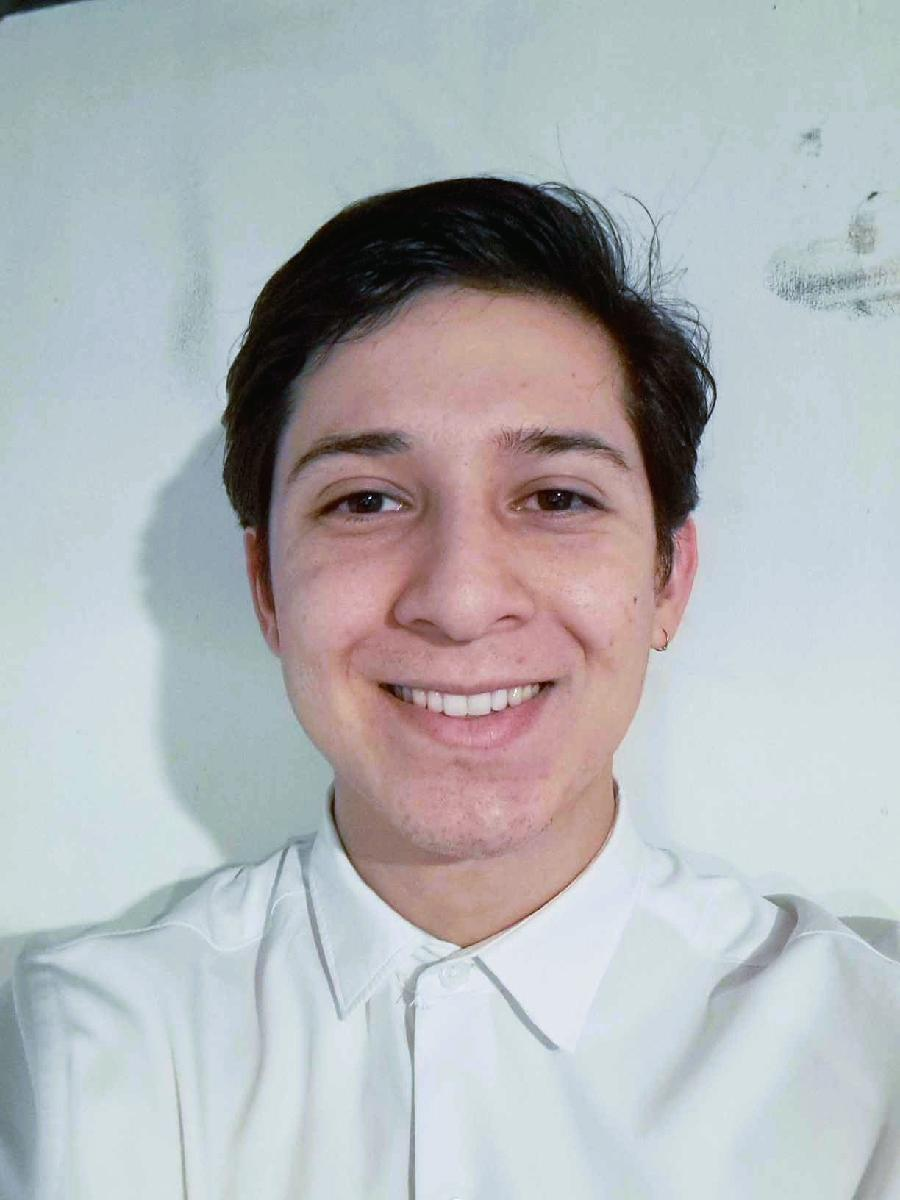

Nombre del alumno: **Jesus Zamora Cervantes**

Número de control: **21212185**

Correo institucional: **l21212185@tectijuana.edu.mx**

Carrera: **Ingeniería Biomédica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Simulation data

clc; clear; close all; warning ('off','all')
or = [0.8500 0.3250 0.0980];
pr = [0.4940 0.1840 0.5560];
gr = [0.4660 0.6740 0.1880];
fred =	[1 0 0];
cy = [0.3010 0.7450 0.9330];


## Parameters and initial conditions

alpha = 0.5; beta = 0.01; delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];
x0 = 75; y0 = 75; tend = 100;

## Solution by Euler's method

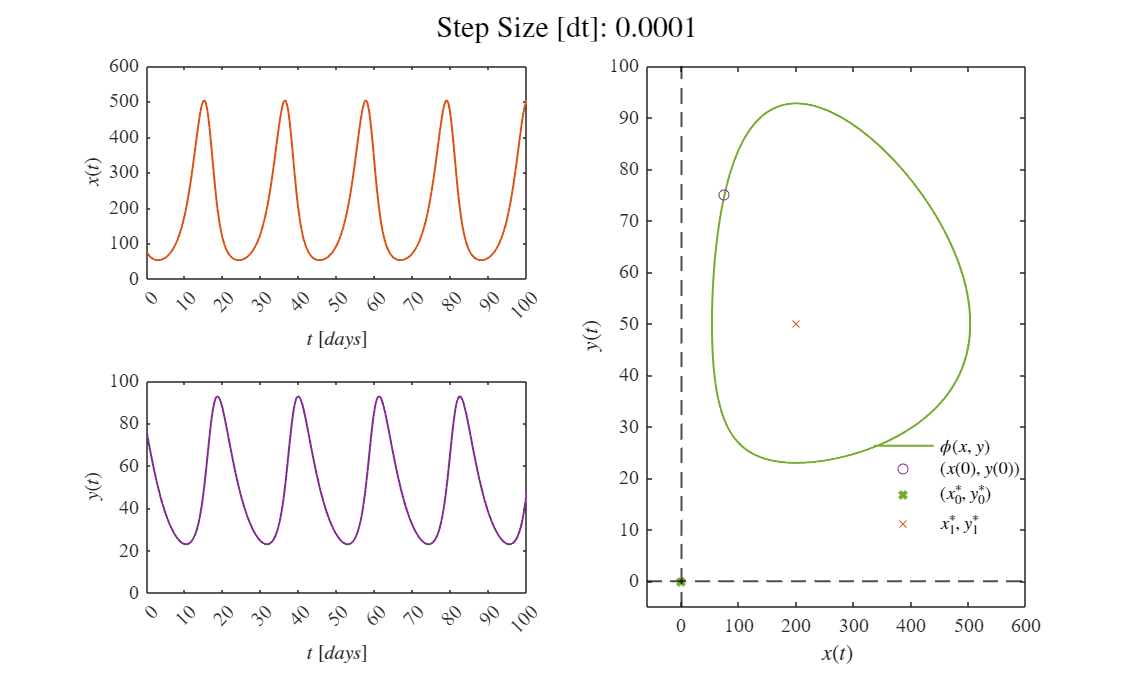

% dt = [2,1,0.5,0.25,1E-1,1E-2,1E-3,1E-4,1E-5,1E-6]; 
dt = 1E-4;
for i = 1:numel(dt)
    [t,x,y] = sys_Euler(x0,y0,dt(i),tend,P);
    plotEDOs(t,x,y,P,dt(i))
    exportgraphics(gcf, ['Lotka-Volterra Euler ', num2str(dt(i)), '.pdf'],'ContentType', 'Vector')
end 

## Solution by Heun's method

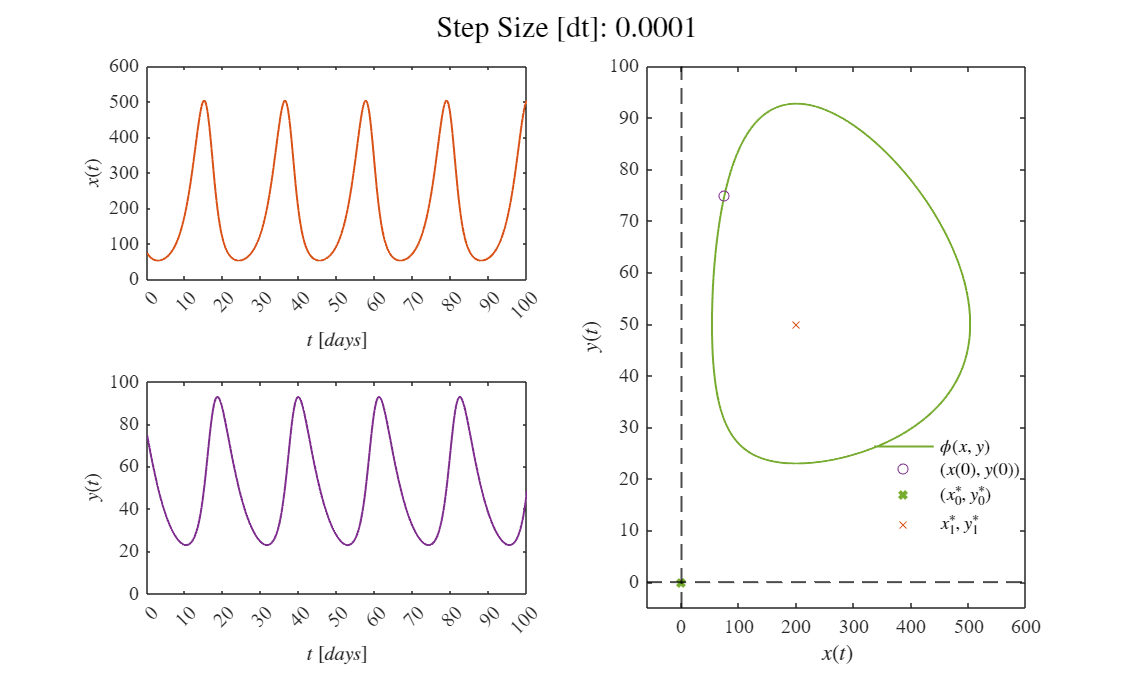

% dt = [2,1,0.5,0.25,1E-1];
for i = 1:numel(dt)
    [t,x,y] = sys_Heun(x0,y0,dt(i),tend,P);
    plotEDOs(t,x,y,P,dt(i))
    exportgraphics(gcf, ['Lotka-Volterra Heun ', num2str(dt(i)), '.pdf'],'ContentType', 'Vector')
end 

## Simulink 

file = 'LotkaVolterra';
sim(file)
parameters.StopTime = '100';

### Solution by Ode15s [Stiff solver]

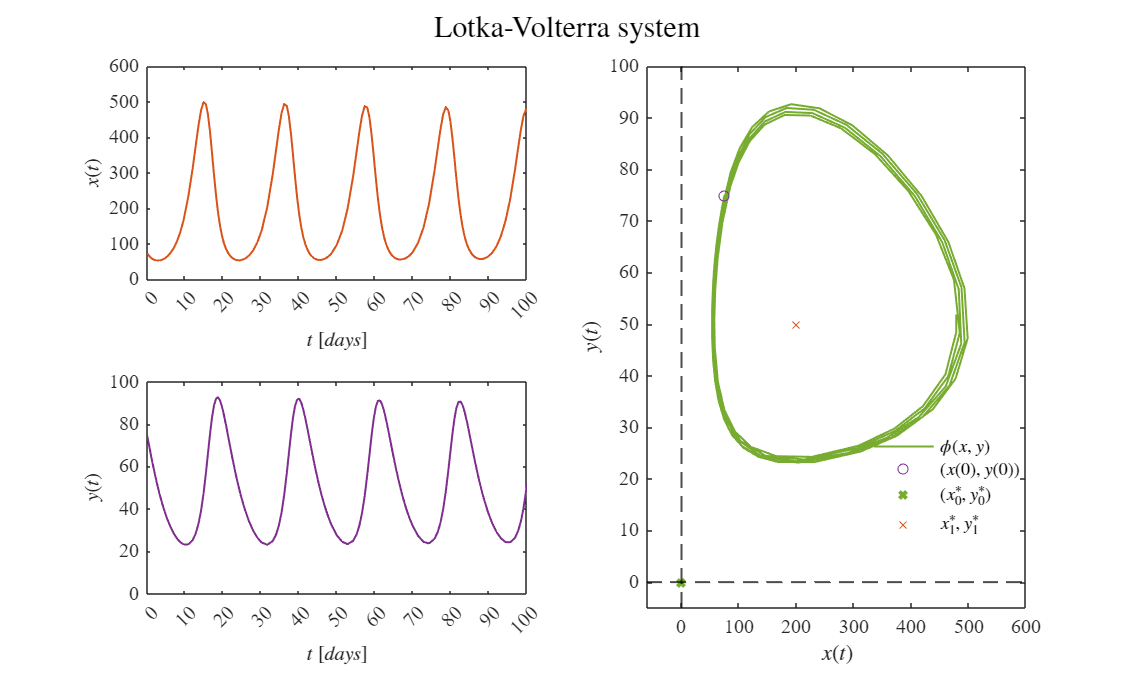

parameters.Solver = 'ode15s';
s15s = sim(file,parameters);
plotEDOs(s15s.t,s15s.x,s15s.y,P,0)
exportgraphics(gcf, ['Lotka-Volterra Ode15s ', num2str(dt(i)), '.pdf'],'ContentType', 'Vector')

### Solution by Ode23s [Stiff solver]

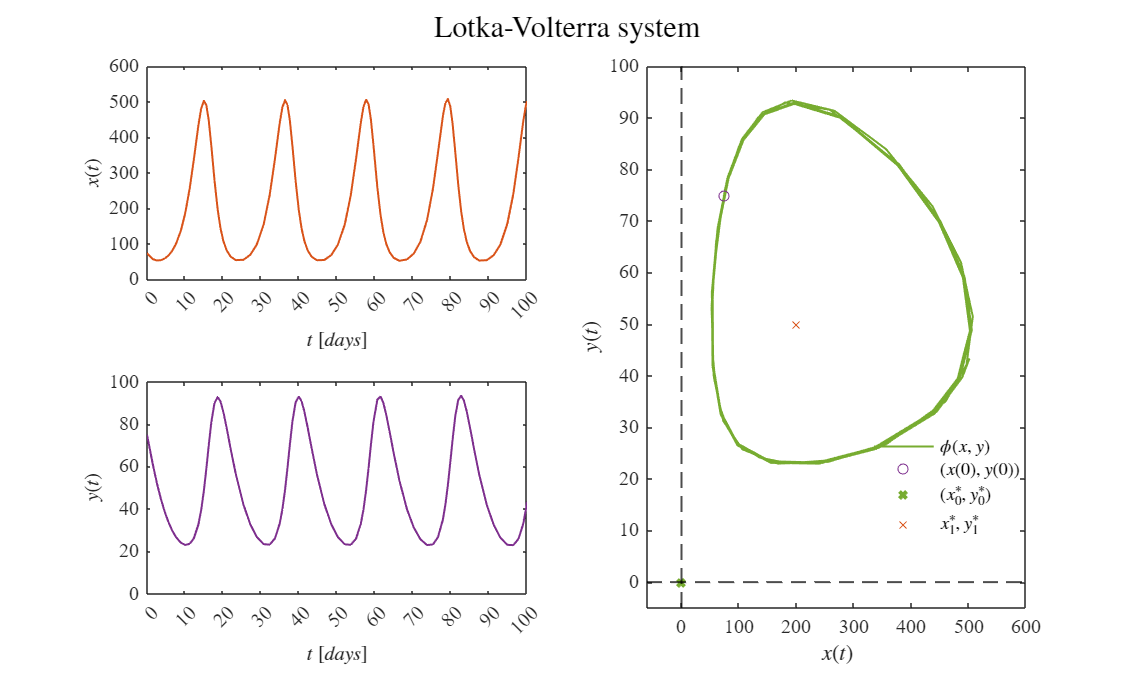

parameters.Solver = 'ode23s';
s23s = sim(file,parameters);
plotEDOs(s23s.t,s23s.x,s23s.y,P,0)
exportgraphics(gcf, ['Lotka-Volterra Ode23s ', num2str(dt(i)), '.pdf'],'ContentType', 'Vector')

### Solution by Ode23t [Stiff solver]

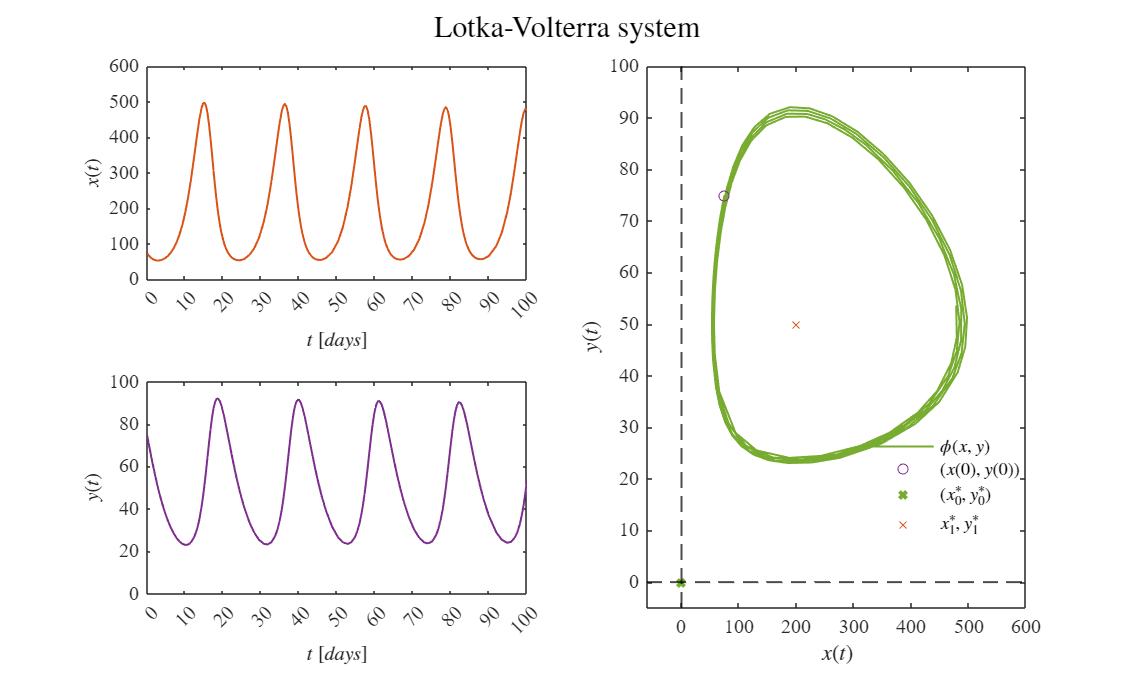

parameters.Solver = 'ode23t';
s23t = sim(file,parameters);
plotEDOs(s23t.t,s23t.x,s23t.y,P,0)
exportgraphics(gcf, ['Lotka-Volterra Ode23t ', num2str(dt(i)), '.pdf'],'ContentType', 'Vector')

### Solution by Ode23tb [Stiff solver]

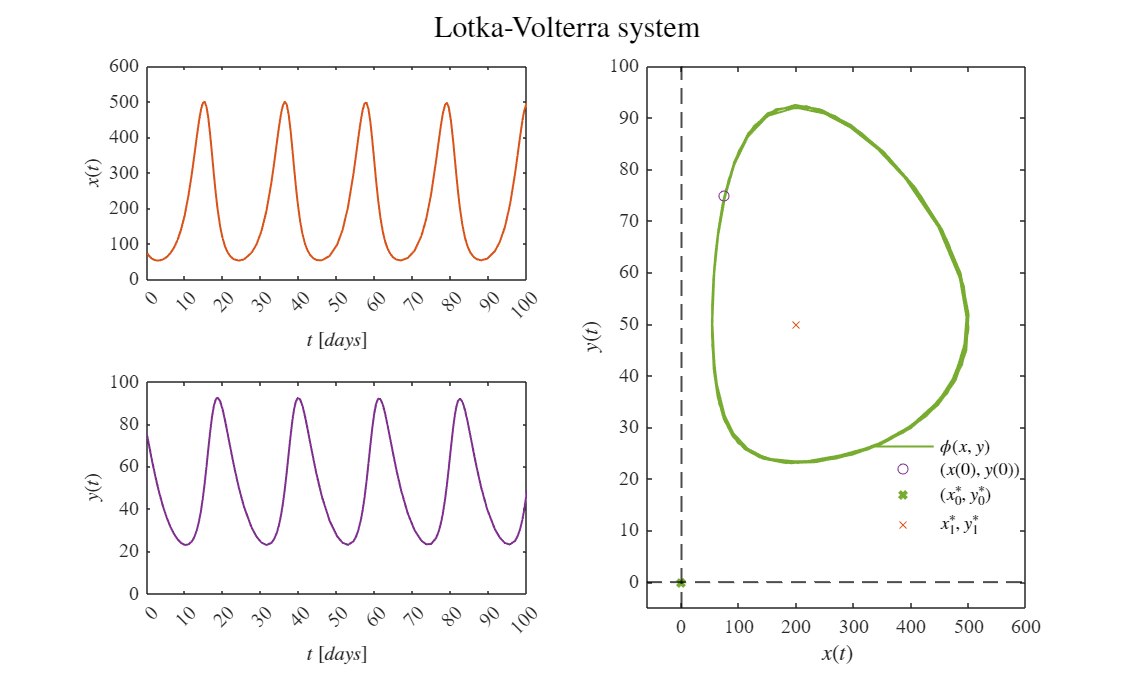

parameters.Solver = 'ode23tb';
s23tb = sim(file,parameters);
plotEDOs(s23tb.t,s23tb.x,s23tb.y,P,0)
exportgraphics(gcf, ['Lotka-Volterra Ode23tb ', num2str(dt(i)), '.pdf'],'ContentType', 'Vector')

### Solution by Ode45 [NonStiff solver]

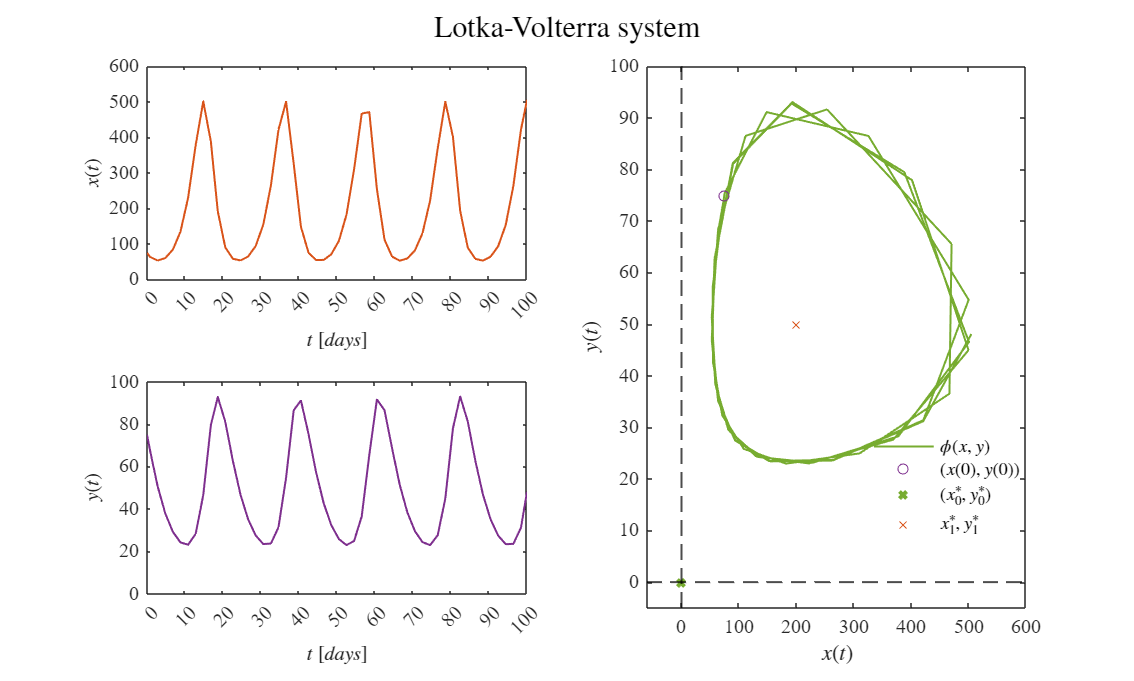

parameters.Solver = 'ode45';
s45 = sim(file,parameters);
plotEDOs(s45.t,s45.x,s45.y,P,0)
exportgraphics(gcf, ['Lotka-Volterra Ode45 ', num2str(dt(i)), '.pdf'],'ContentType', 'Vector')

### Solution by Ode113 [NonStiff solver]

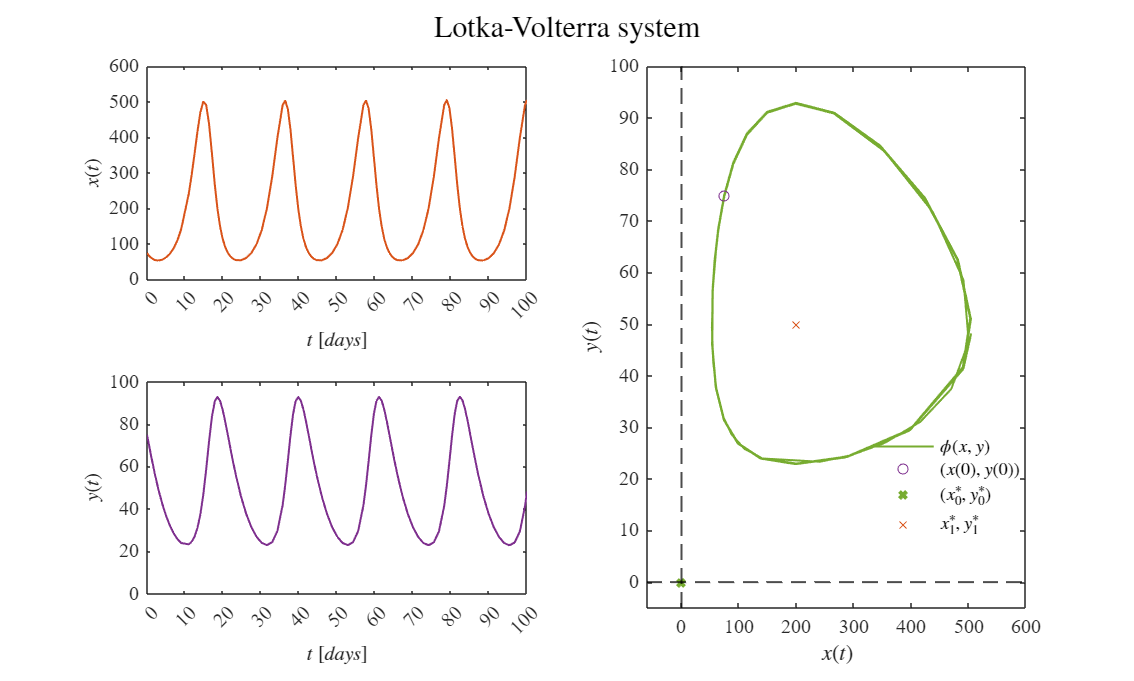

parameters.Solver = 'ode113';
s113 = sim(file,parameters);
plotEDOs(s113.t,s113.x,s113.y,P,0)
exportgraphics(gcf, ['Lotka-Volterra Ode113 ', num2str(dt(i)), '.pdf'],'ContentType', 'Vector')

Con base en las simulaciones numéricas, se determinó que el solucionador ODE con mayor precisión es el **ode113**. Este método pertenece a la categoría de solucionadores *Nonstiff*, Esto significa que no hay diferencias muy grandes en las escalas de tiempo de las variables del sistema, lo que permite resolverlo de manera eficiente con métodos explícitos como ode45 aunque en este caso no fue muy eficiente. Debido a esto el sistema no presenta rígidez, por lo tanto se concluye que el modelo de Lotka-Volterra es *Nonstiff.*

C. Moler "*NonStiff Differential Equations*" MathWorks. Accesed: Feb. 24, 2025 [Online]. Available: [https://la.mathworks.com/company/technical-articles/stiff-differential-equations.html#](https://la.mathworks.com/company/technical-articles/stiff-differential-equations.html#)

### Equilibriuam points and Jacobian matrix

clear; close all; clc;
syms x y alpha beta delta gamma
dx = alpha*x - beta*x*y;
dy = delta*x*y - gamma*y;
J = jacobian([dx,dy],[x,y]);
fprintf('Jacobian matrix of Lotka-Volterra system:'); disp(J)

Jacobian matrix of Lotka-Volterra system:

$$\left(\begin{array}{cc} \alpha -\beta \,y & -\beta \,x\\ \delta \,y & \delta \,x-\gamma \end{array}\right)$$

dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
edos = solve([dx,dy],[x,y]);
fprintf(['The Lotka-Volterra system has ', num2str(length(edos.x)), ' equilibrius points. '])

The Lotka-Volterra system has 2 equilibrius points. 

X0 = edos.x(1); Y0 = edos.y(1);
X1 = edos.x(2); Y1 = edos.y(2);
syms x0 y0 x1 y1
fprintf('Equilibrium points of the Lotka-Volterra system: ');...
    disp([x0,y0,X0,Y0]); disp(([x1,y1,X1,Y1]))

Equilibrium points of the Lotka-Volterra system: 

$$\left(\begin{array}{cccc} x_{0} & y_{0} & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{1} & y_{1} & \frac{\gamma }{\delta } & \frac{\alpha }{\beta } \end{array}\right)$$

clear alpha beta delta gamma
alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
disp('(x0,y0) = (0,0)');...
    disp(['(x1,y1) = (' num2str(gamma/delta), ',', num2str(alpha/beta), ')'])

(x0,y0) = (0,0)


(x1,y1) = (200,50)


### Local stability

clc; clear;
alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
syms x y
dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
edos = solve([dx,dy],[x,y]);
fprintf(['The Lotka-Volterra system has ', num2str(length(edos.x)), ' equilibrius points. '])

The Lotka-Volterra system has 2 equilibrius points. 

x0 = double(edos.x(1)); y0 = double(edos.y(1));
x1 = double(edos.x(2)); y1 = double(edos.y(2));
clear x y
x = [x0; x1]; y = [y0; y1];
var = {'(x0,y0)';'(x1,y1)'};
Equilibria = table(x,y,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye'};
fprintf('Equilibrium points of the Lotka-Volterra system:\n'); disp(Equilibria)

Equilibrium points of the Lotka-Volterra system:
          xe     ye
          ___    __

    …      0     0
    …    200    50




L = zeros(length(x),length(x));
for i = 1:length(x)
    J = [alpha - beta*y(i), -beta*x(i);
        delta*y(i), delta*x(i) - gamma];
    L(i,:) = eig(J);
end
L1 = L(:,1); L2 = L(:,2);
Lambdas = table(L1,L2, 'RowNames',var);
disp('Eigen values of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas)

Eigen values of the Jacobian matrix evaluated at each equilibrium point:
               L1               L2     
          _____________    ____________

    …    -0.2+0i          0.5+0i      
    …       0+0.31623i      0-0.31623i



Con base en el análisis anterior, el primer punto de equilibrio es inestable (punto de silla), debido a que sus raíces son reales pero con diferente signo, según el teorema de estabilidad. Mientras que el segundo punto de equilibrio al tener raíces imaginarias mantiene una estabilidad neutra en la que el sistema realiza oscilaciones sostenidas.

### Equilibrium points

alpha = 0.5;    beta = 0.01;
delta = 0.001;  gamma = 0.2;
P = [alpha,beta,delta,gamma];
x0 = 75; y0 = 75; tend = 100;
dt = 1E-4;
[t,x,y] = sys_Heun(x0,y0,dt,tend,P);
plotEDOs(t,x,y,P,dt); ttl = 'Lotka-Volterra system';
         sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf, 'Lotka-Volterra Equilibria.pdf','ContentType','Vector')

### Data fitting

clc; clear; close all

### Raw data

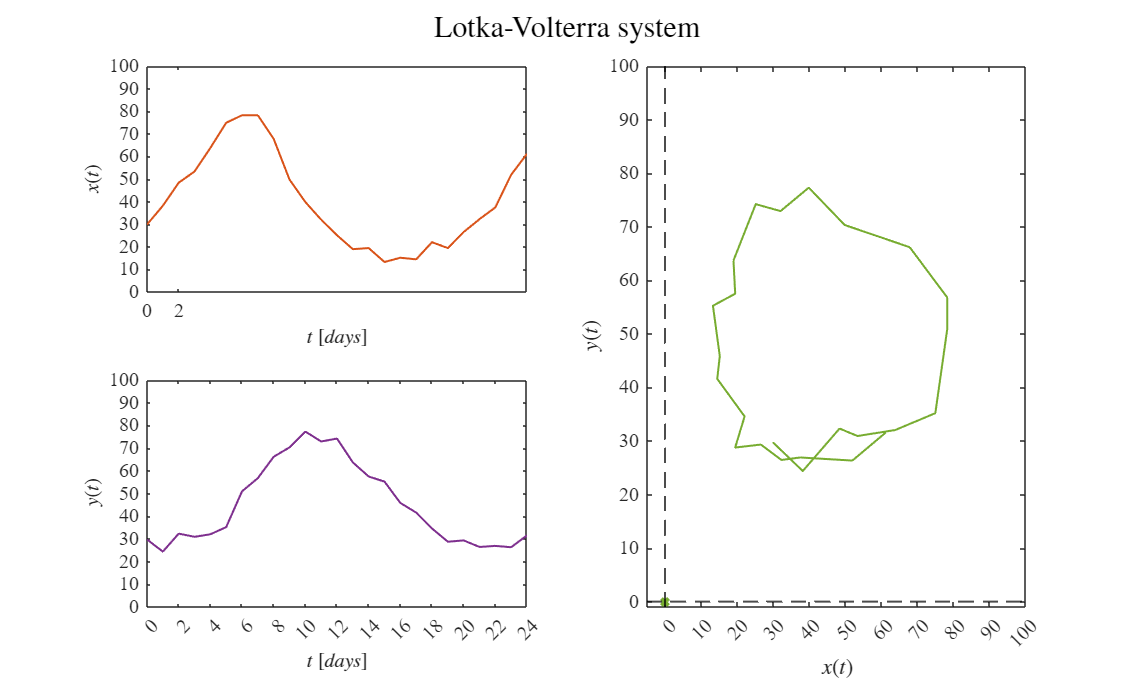

sys = readmatrix ('data.csv');
to = sys(:,1); xo = sys(:,2); yo = sys(:,3);
T = array2table([to,xo,yo],'VariableNames',{'t [min]', 'X','Y'});
alpha = 0.5;    beta = 0.01;
delta = 0.001;  gamma = 0.2;
P = [alpha,beta,delta,gamma];
plotEDOsfit(to,xo,yo,P,0); ttl = 'Lotka-Volterra system';
         sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf, 'data fitting Lotka-Volterra.pdf','ContentType','Vector')

### Smooth data

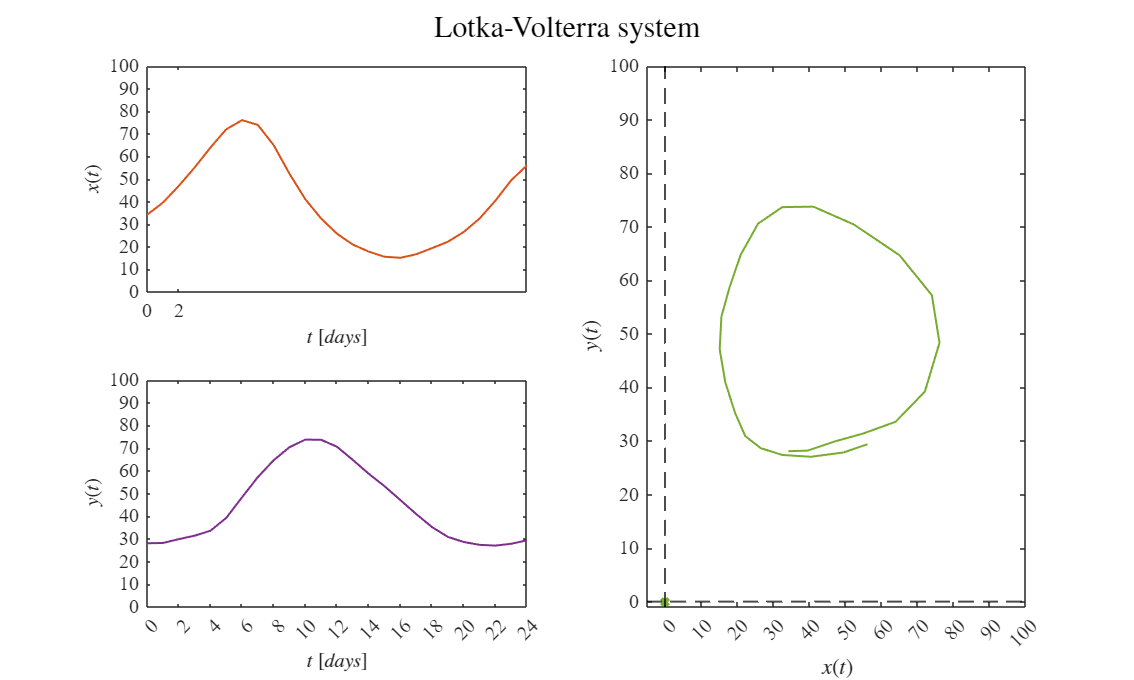

xo = smoothdata(xo,'gaussian',5);
yo = smoothdata(yo,'gaussian',5);
plotEDOsfit(to,xo,yo,P,0);
ttl = 'Lotka-Volterra system';
         sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf, 'data fitting Lotka-Volterra (smooth).pdf','ContentType','Vector')

### Fit data

P0 = [1;0.01;0.01;0.1];
mdl = variant(to,xo,yo,P0);


Sample size (n): 25
Parameters to be estimated (pars): 4
Degrees of freedom: 46
Significance level (alpha): 0.05
t-Student value: 2.0129
Adjusted R-squared: 0.99261
Corrected AIC (n/pars < 40): 192.4875

    Parameters    Estimate         SE           MoE                 CI95               pvalue  
    __________    _________    __________    __________    ______________________    __________

      alpha         0.42493     0.0072169      0.014527       0.4104      0.43946    5.8107e-45
       beta       0.0089383    0.00017978    0.00036188    0.0085764    0.0093002    1.2356e-41
      delta       0.0053499    0.00010599    0.00021334    0.0051366    0.0055632    6.2246e-42
      gamma          0.2176     0.0044322     0.0089215      0.20868      0.22653    2.1797e-41



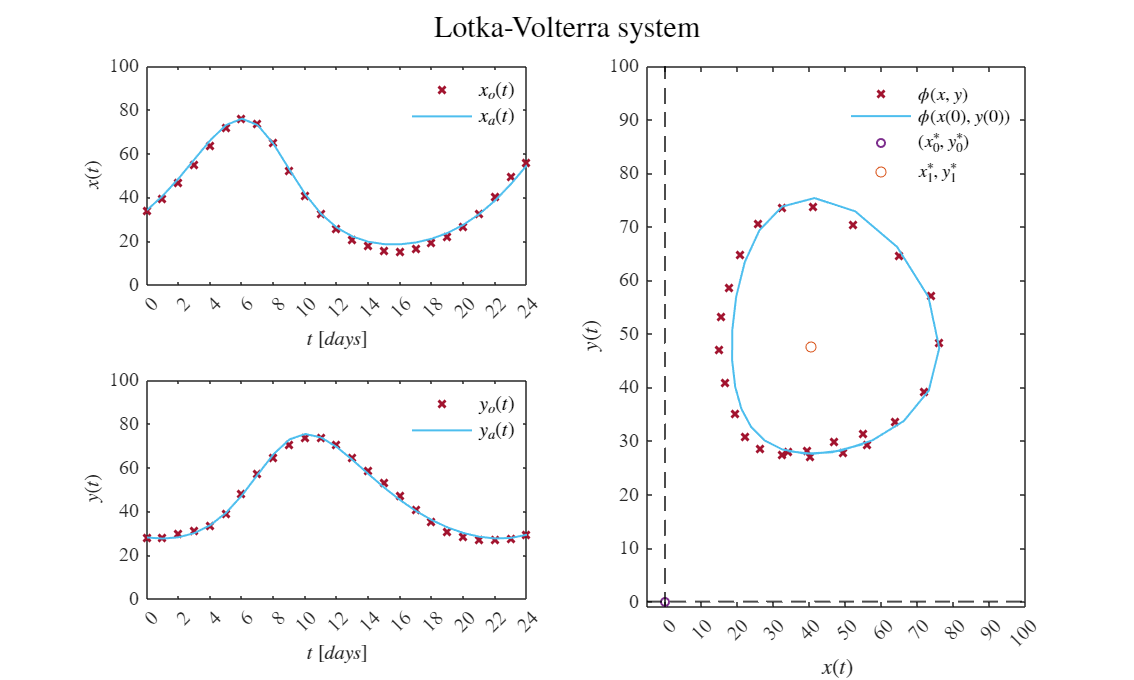

fa = mdl.Fitted;
fx = reshape(fa,[],2);
xa = fx(:,1); ya = fx(:,2);
P = table2array(mdl.Coefficients(:,1));
plotResults(to,[xo,xa],[yo,ya],P)
ttl = 'Lotka-Volterra system';
         sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf, 'results data Lotka-Volterra .pdf','ContentType','Vector')

## Experimental data (zooplankton and phytoplankton)

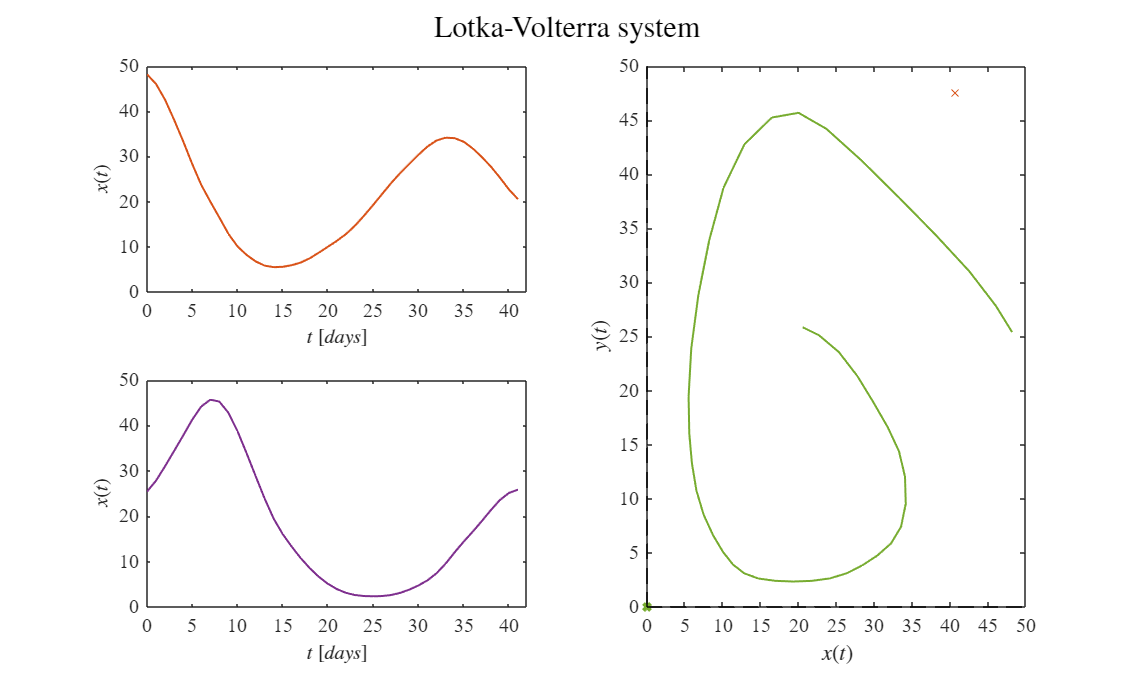

sys = readmatrix ('zoofito.csv');
to = sys(:,1); xo = sys(:,2); yo = sys(:,3);
T = array2table([to,xo,yo],'VariableNames',{'t [min]', 'X','Y'});
alpha = 0.5;    beta = 0.001;
delta = 0.005;  gamma = 0.05;
P = table2array(mdl.Coefficients(:,1));
xo = smoothdata(xo,'gaussian',5);
yo = smoothdata(yo,'gaussian',5);
plotEDOsfit2(to,xo,yo,P,0);
ttl = 'Lotka-Volterra system';
         sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf, 'Zoo-Fito Lotka-Volterra (smooth).pdf','ContentType','Vector')

### Fit data (zooplankton and phytoplankton)

P0 = [1;0.01;0.01;0.1];
mdl = variant2(to,xo,yo,P0);


Sample size (n): 42
Parameters to be estimated (pars): 4
Degrees of freedom: 80
Significance level (alpha): 0.05
t-Student value: 1.9901
Adjusted R-squared: 0.74911
Corrected AIC (n/pars < 40): 560.0846

    Parameters    Estimate         SE           MoE                CI95               pvalue  
    __________    _________    __________    _________    ______________________    __________

      alpha         0.16821      0.018489     0.036794      0.13141        0.205    5.6442e-14
       beta       0.0082906    0.00085129    0.0016941    0.0065965    0.0099847    3.1251e-15
      delta       0.0081195     0.0007427     0.001478    0.0066415    0.0095975    1.5179e-17
      gamma         0.18672      0.020376     0.040549      0.14617      0.22727    4.1908e-14



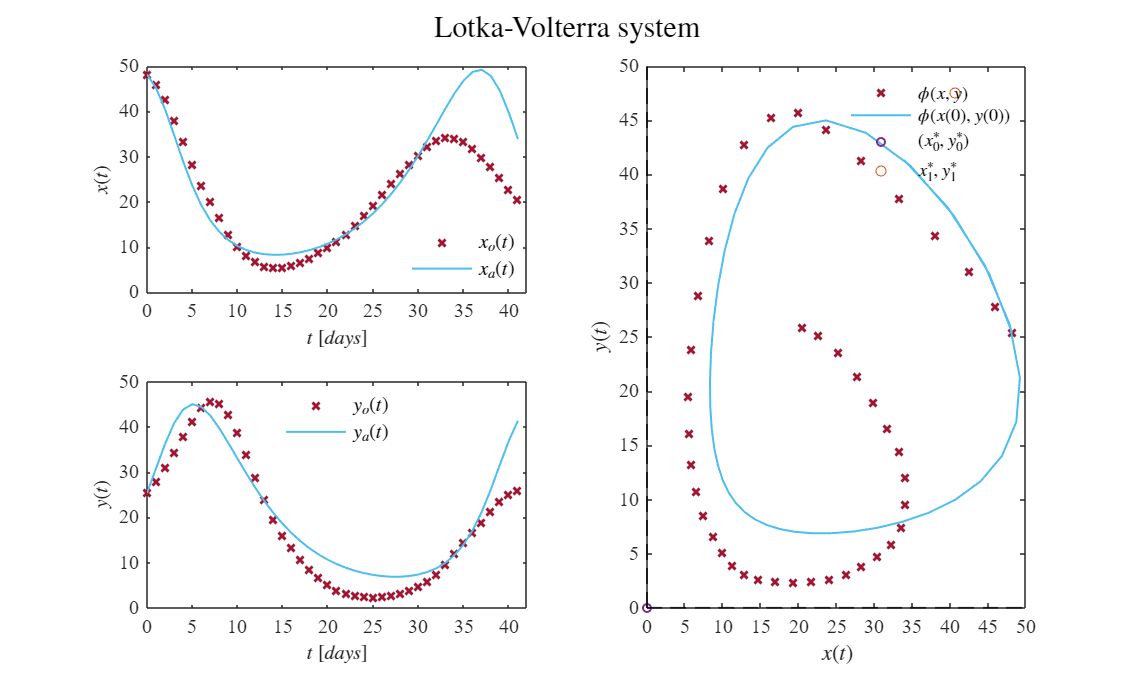

fa = mdl.Fitted;
fx = reshape(fa,[],2);
xa = fx(:,1); ya = fx(:,2);
plotResults2(to,[xo,xa],[yo,ya],P)
ttl = 'Lotka-Volterra system';
         sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf, 'results2 data Lotka-Volterra .pdf','ContentType','Vector')

## Functions

### Euler's method

function [t,x,y] = sys_Euler(x0,y0,dt,tend,P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend/dt);
    t = (0:dt:tend)';
    x = zeros(length(t),1); x(1) = x0;
    y = zeros(length(t),1); y(1) = y0;

    for i = 1:n
        x(i+1) = x(i) +  (alpha * x(i) - beta * x(i) * y(i))*dt;
        y(i+1) = y(i) +  (delta * x(i) * y(i) - gamma * y(i))*dt;
    end 
   

end

### Heun's method

function [t, x, y] = sys_Heun(x0, y0, dt, tend, P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend / dt);
    t = (0:dt:tend)';
    
    x = zeros(length(t), 1); x(1) = x0;
    y = zeros(length(t), 1); y(1) = y0;

    for i = 1:n
        [fx,fy] = f(x(i),y(i));
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt;
        [fxn,fyn] = f(xn,yn);

        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
    end

    function [dx,dy] = f(x,y)
        dx = alpha*x - beta*x*y;
        dy = delta*x*y - gamma*y;
    end
end

### Solutions and trajectories 

function plotEDOs(t,x,y,P,dt)
    set(figure(),'Color','w')
    or = [0.8500 0.3250 0.0980];
    pr = [0.4940 0.1840 0.5560];
    gr = [0.4660 0.6740 0.1880];
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth', 1, 'Color',or)
    xlabel('$t$ $[days]$', 'Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 600]); yticks(0:100:600)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth', 1, 'Color',pr)
    xlabel('$t$ $[days]$', 'Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,[2 4])
    set(gca,'FontName','Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(x,y,'-','LineWidth', 1, 'Color',gr)
    plot(x(1),y(1),'o','MarkerSize',5,'Color',pr)
    plot(0,0,'x','MarkerSize',5,'LineWidth',2,'Color',gr)
    plot(gamma/delta,alpha/beta,'x','MarkerSize',5,'Color',or)
    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([-60 600]); xticks(0:100:600)
    ylim([-5 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    L = legend('$\phi(x,y)$','$(x(0),y(0))$','$(x^*_0,y^*_0)$','$x^*_1,y^*_1$');
    set (L,'Interpreter','latex','Location','none','Position', [0.778, 0.263, 0.115,0.041],'Box','off')
    


    if dt == 0
    ttl = 'Lotka-Volterra system';
    sgtitle(ttl,'Interpreter','Latex')
    else
    ttl = ['Step Size [dt]: ', num2str(dt)];
    sgtitle(ttl,'Interpreter','latex')
    end


end

function plotEDOsfit(to,xo,yo,P,dt)
    set(figure(),'Color','w')
    or = [0.8500 0.3250 0.0980];
    pr = [0.4940 0.1840 0.5560];
    gr = [0.4660 0.6740 0.1880];
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);


    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(to,xo,'-','LineWidth', 1, 'Color',or)
    xlabel('$t$ $[days]$', 'Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    xlim([0 24]); xticks(0:2:2)
    ylim([0 100]); yticks(0:10:100)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(to,yo,'-','LineWidth', 1, 'Color',pr)
    xlabel('$t$ $[days]$', 'Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:10:100)

    subplot(2,2,[2 4])
    set(gca,'FontName','Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(xo,yo,'-','LineWidth', 1, 'Color',gr)
    plot(0,0,'x','MarkerSize',5,'LineWidth',2,'Color',gr)
    plot(gamma/delta,alpha/beta,'x','MarkerSize',5,'Color',or)
    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([-5 100]); xticks(0:10:100)
    ylim([-1 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    


    if dt == 0
    ttl = 'Lotka-Volterra system';
    sgtitle(ttl,'Interpreter','Latex')
    else
    ttl = ['Step Size [dt]: ', num2str(dt)];
    sgtitle(ttl,'Interpreter','latex')
    end

end

function plotResults(t,x,y,P)
set(figure(),'Color','w')
    rd = [0.6350 0.0780 0.1840];
    cy = [0.3010 0.7450 0.9330];
    gr = [0.4660 0.6740 0.1880];
    pr = [0.4940 0.1840 0.5560];
    or = [0.8500 0.3250 0.0980];
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);


    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5, 'Color',rd)
    plot(t,x(:,2),'-','LineWidth',1, 'Color',cy)
    xlabel('$t$ $[days]$', 'Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    L = legend('$x_o(t)$','$x_a(t)$');
    set (L,'Interpreter','latex','Location','Best','Box','off')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5, 'Color',rd)
    plot(t,y(:,2),'-','LineWidth',1, 'Color',cy)
    xlabel('$t$ $[days]$', 'Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    L = legend('$y_o(t)$','$y_a(t)$');
    set (L,'Interpreter','latex','Location','Best','Box','off')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,[2 4])
    set(gca,'FontName','Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(x(:,1),y(:,1),'x','MarkerSize', 5,'LineWidth',1.5,'Color',rd)
    plot(x(:,2),y(:,2),'-','LineWidth',1,'Color',cy)
    plot(0,0,'o','MarkerSize',4,'LineWidth',1,'Color',pr)
    plot(gamma/delta,alpha/beta,'o','MarkerSize',5,'Color',or)
    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([-5 100]); xticks(0:10:100)
    ylim([-1 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    L = legend('$\phi(x,y)$','$\phi(x(0),y(0))$','$(x^*_0,y^*_0)$','$x^*_1,y^*_1$');
    set (L,'Interpreter','latex','Location','Best','Box','off')
end 

function plotEDOsfit2(to,xo,yo,P,dt)
    set(figure(),'Color','w')
    or = [0.8500 0.3250 0.0980];
    pr = [0.4940 0.1840 0.5560];
    gr = [0.4660 0.6740 0.1880];
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);


    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(to,xo,'-','LineWidth', 1, 'Color',or)
    xlabel('$t$ $[days]$', 'Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    xlim([0 42]); xticks(0:5:42)
    ylim([0 50]); yticks(0:10:50)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(to,yo,'-','LineWidth', 1, 'Color',pr)
    xlabel('$t$ $[days]$', 'Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    xlim([0 42]); xticks(0:5:42)
    ylim([0 50]); yticks(0:10:50)

    subplot(2,2,[2 4])
    set(gca,'FontName','Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(xo,yo,'-','LineWidth', 1, 'Color',gr)
    plot(0,0,'x','MarkerSize',5,'LineWidth',2,'Color',gr)
    plot(gamma/delta,alpha/beta,'x','MarkerSize',5,'Color',or)
    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([0 50]); xticks(0:5:50)
    ylim([0 50]); yticks(0:5:50)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    
end
function plotResults2(t,x,y,P)
set(figure(),'Color','w')
    rd = [0.6350 0.0780 0.1840];
    cy = [0.3010 0.7450 0.9330];
    gr = [0.4660 0.6740 0.1880];
    pr = [0.4940 0.1840 0.5560];
    or = [0.8500 0.3250 0.0980];
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);


    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5, 'Color',rd)
    plot(t,x(:,2),'-','LineWidth',1, 'Color',cy)
    xlabel('$t$ $[days]$', 'Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    L = legend('$x_o(t)$','$x_a(t)$');
    set (L,'Interpreter','latex','Location','Best','Box','off')
    xlim([0 42]); xticks(0:5:42)
    ylim([0 50]); yticks(0:10:50)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5, 'Color',rd)
    plot(t,y(:,2),'-','LineWidth',1, 'Color',cy)
    xlabel('$t$ $[days]$', 'Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    L = legend('$y_o(t)$','$y_a(t)$');
    set (L,'Interpreter','latex','Location','Best','Box','off')
    xlim([0 42]); xticks(0:5:42)
    ylim([0 50]); yticks(0:10:50)

    subplot(2,2,[2 4])
    set(gca,'FontName','Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off;
    plot(x(:,1),y(:,1),'x','MarkerSize', 5,'LineWidth',1.5,'Color',rd)
    plot(x(:,2),y(:,2),'-','LineWidth',1,'Color',cy)
    plot(0,0,'o','MarkerSize',4,'LineWidth',1,'Color',pr)
    plot(gamma/delta,alpha/beta,'o','MarkerSize',5,'Color',or)
    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([0 50]); xticks(0:5:50)
    ylim([0 50]); yticks(0:5:50)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    L = legend('$\phi(x,y)$','$\phi(x(0),y(0))$','$(x^*_0,y^*_0)$','$x^*_1,y^*_1$');
    set (L,'Interpreter','latex','Location','Best','Box','off')
end 





### Nonlinear regression algorithm

function  mdl = variant(to,xo,yo,P0)
  x0 = xo(1); y0 = yo(1);
  to = [to;to];
  fo = [xo;yo];

    function fi = model(p,t)
        alpha = p(1); beta = p(2); delta = p(3); gamma = p(4);
        dt = 1E-1;
        t = reshape(t,[],2); t = t(:,1); %cambia la forma del arreglo t, columna a matriz%
        time = (0:dt:max(t));  %Para Heun%
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = x0;
        y = zeros(length(time),1); y(1) = y0;

     
        for i = 1:n
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);
    
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end
    
        function [dx,dy] = f(x,y)
            dx = alpha*x - beta*x*y;
            dy = delta*x*y - gamma*y;
        end

        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        for j = 1:length(t)
            k = abs(time - t(j)) < 1E-9;
            xi(j) = x(k); 
            yi(j) = y(k);
        end
        fi = [xi;yi];
    end 
        mdl = fitnlm(to,fo,@model,P0);

        Estimate = table2array(mdl.Coefficients(:,1));
        SE = table2array(mdl.Coefficients(:,2));
        pvalue = table2array(mdl.Coefficients(:,4));
        alpha = 0.05;
        CI95 = coefCI(mdl,alpha);
        dof = mdl.DFE;
        tval = tinv(1-alpha/2,dof);
        MoE = SE*tval;
        Parameters = ['alpha';' beta';'delta';'gamma'];
        Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);
        
        fprintf(['\nSample size (n): ', num2str(numel(xo))]) 
        fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
        fprintf(['\nDegrees of freedom: ', num2str(dof)])
        fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
        fprintf(['\nt-Student value: ', num2str(tval)])
        fprintf(['\nAdjusted R-squared: ', num2str(mdl.Rsquared.Adjusted)])
        fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
        disp(Results)

end


function  mdl = variant2(to,xo,yo,P0)
  x0 = xo(1); y0 = yo(1);
  to = [to;to];
  fo = [xo;yo];

    function fi = model(p,t)
        alpha = p(1); beta = p(2); delta = p(3); gamma = p(4);
        dt = 1E-1;
        t = reshape(t,[],2); t = t(:,1); %cambia la forma del arreglo t, columna a matriz%
        time = (0:dt:max(t));  %Para Heun%
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = max(x0,eps);
        y = zeros(length(time),1); y(1) = max(y0,eps);

     
        for i = 1:n
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(max(xn, eps), max(yn, eps));
    
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end
    
        function [dx,dy] = f(x,y)
            dx = alpha*x - beta*x*y;
            dy = delta*x*y - gamma*y;
        end

        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        for j = 1:length(t)
            k = abs(time - t(j)) < 1E-9;
            xi(j) = x(k); 
            yi(j) = y(k);
        end
        fi = [xi;yi];
    end 
        mdl = fitnlm(to,fo,@model,P0);

        Estimate = table2array(mdl.Coefficients(:,1));
        SE = table2array(mdl.Coefficients(:,2));
        pvalue = table2array(mdl.Coefficients(:,4));
        alpha = 0.05;
        CI95 = max(coefCI(mdl,alpha),eps);
        dof = mdl.DFE;
        tval = tinv(1-alpha/2,dof);
        MoE = SE*tval;
        Parameters = ['alpha';' beta';'delta';'gamma'];
        Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);
        
        fprintf(['\nSample size (n): ', num2str(numel(xo))]) 
        fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
        fprintf(['\nDegrees of freedom: ', num2str(dof)])
        fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
        fprintf(['\nt-Student value: ', num2str(tval)])
        fprintf(['\nAdjusted R-squared: ', num2str(mdl.Rsquared.Adjusted)])
        fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
        disp(Results)

end